# CIE Metamerism Index

Q: how to evaluate Mu, Mv shown in papers by Tommy Wei?

A: implement ISO 23605

## Show the data from ISO standard

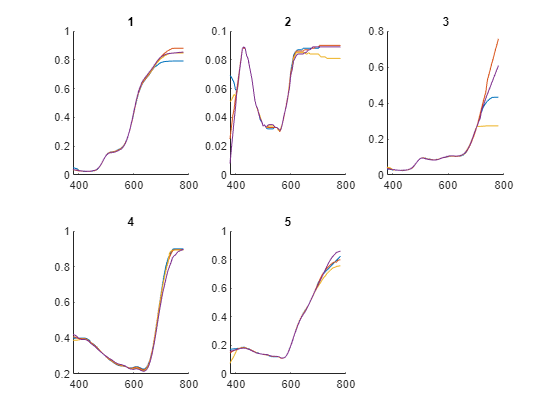

load cie_metamerism_data.mat

spec_ref = specimen;

sp4{1} = spec_d50;
sp4{2} = spec_d55;
sp4{3} = spec_d65;
sp4{4} = spec_d75;

clf
for material_no = 1:5
    subplot(2,3,material_no)
    hold on
    for i = 1:4
        sp = sp4{i};
        plot(sp(:,1),sp(:,1+material_no))
    end
    title(material_no)
end

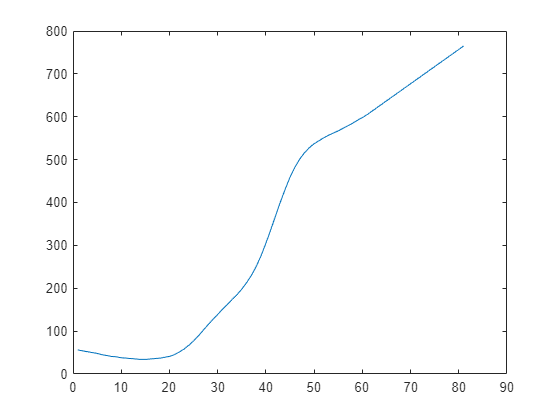

reflectance = specimen(:,2);
clf
plot(reflectance)

## Compare with mine

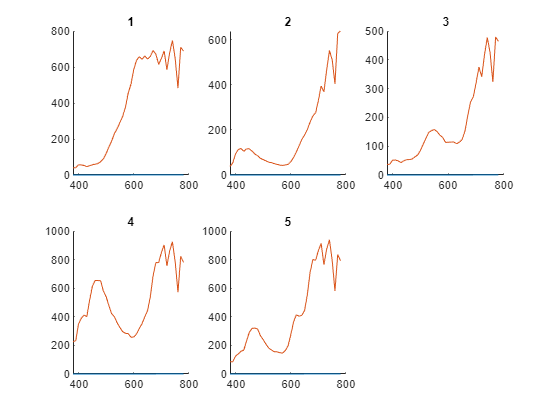

%my_speC_d65 = CIE_D.getSpectrum(6000);
%my_d65 = my_speC_d65.amplitude(1:5:end);
cc = ColorConversionClass;
my_d65 = ColorConversionClass.spd_d65;

spec_d65_my = zeros(41,6);
spec_d65_my(:,1) = 380:10:780;
for material_no = 1:5
    col_no = 1+material_no;
    reflectance = spec_ref(:,col_no);
    reflectance = reflectance(1:2:81,1);
    spd = my_d65 .* reflectance;
    spec_d65_my(:,col_no) = spd * 0.15;
end

sp4{5} = spec_d65_my;

clf
for material_no = 1:5
    subplot(2,3,material_no)
    hold on
    for i = [3 5]
        sp = sp4{i};
        plot(sp(:,1),sp(:,1+material_no))
    end
    title(material_no)
end

## Why don't they match?? Need to understand the ISO data